Se sabe que $\frac{\mathrm{d}}{\mathrm{d}x}f\left(x\right)=\lim_{h\to 0} \left(\frac{f\left(x+h\right)-f\left(x\right)}{h}\right)$. Sin embargo, en muchas ocasiones, derivar la derivada de forma analítica puede ser tedioso. Por ello, existe un método numérico que permite realizar la derivada para estos casos.


$$\frac{\mathrm{d}}{\mathrm{d}x}f\left(x_i \right)\approx \frac{f\left(x_i +h\right)-f\left(x_i -h\right)}{2*h}$$


Es recomendable que $h$ sea menor que $\frac{1}{10}$.

f = @(x) (x.^2.*log(x));
syms x
dfdx = diff(f(x))

$$dfdx = x+2\,x\,\log\left(x\right)$$

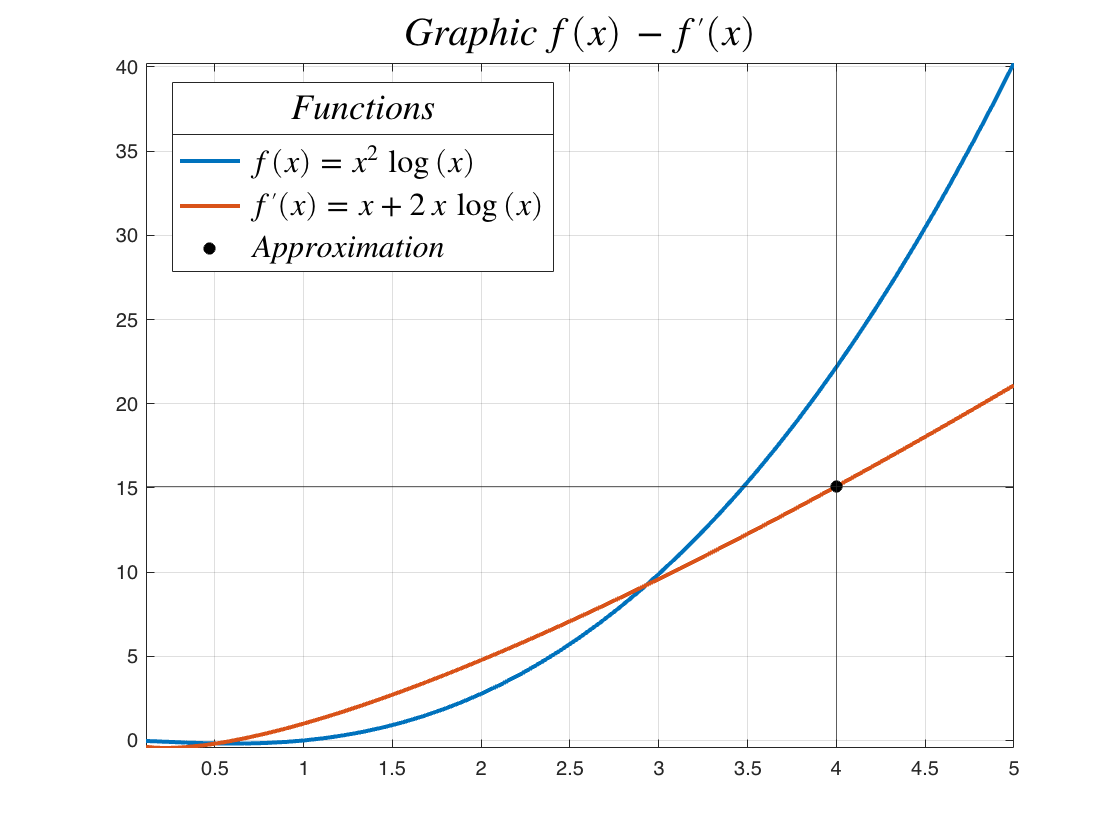

xi = 4.0;
h = 0.001;
[dfxi_aprox] = DerivadaCentrada(f, xi, h);

fplot(f, Color='#0072BD', LineWidth=2);
hold on; grid on;
fplot(dfdx, Color='#D95319', LineWidth=2);
plot(xi, dfxi_aprox, '*', Color='#000000', LineWidth=2)

xline(xi)
yline(dfxi_aprox)

title("$Graphic\,f(x)\,-\,f'(x)$", 'Interpreter','latex', 'FontSize', 20)
lgnd = legend( ...
    {'$f(x)=x^2 \,\log \left(x\right)$', "$f'(x)=x+2\,x\,\log \left(x\right)$", "$Approximation$"} ...
    , 'Interpreter','latex', 'Location','best', 'FontSize', 16);

title(lgnd, '$Functions$', 'Interpreter','latex', 'FontSize', 18)
hold off;

dfxi_real = vpa(subs(dfdx, xi), 15)

$$dfxi\_real = 15.0903548889591$$

dfxi_aprox = vpa(dfxi_aprox, 15)

$$dfxi\_aprox = 15.0903549722941$$

error_absoluto = round(abs(dfxi_real - dfxi_aprox), 10)

$$error\_absoluto = 0.0000000833$$

Se puede comprobar que el método de diferencia centrada aproxima correctamente a la derivada de $f\left(x\right)$ en sus primeros dígitos con un error bastante aceptable.